BIT PLANE SLICING

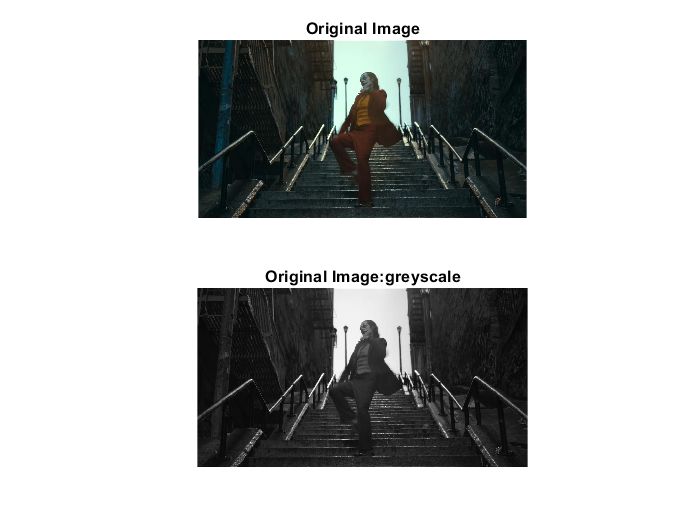

A=imread('000837.jpg');
figure,
subplot(2,1,1);imshow(A);title('Original Image');

A = rgb2gray(A);
subplot(2,1,2);imshow(A);title('Original Image:greyscale');

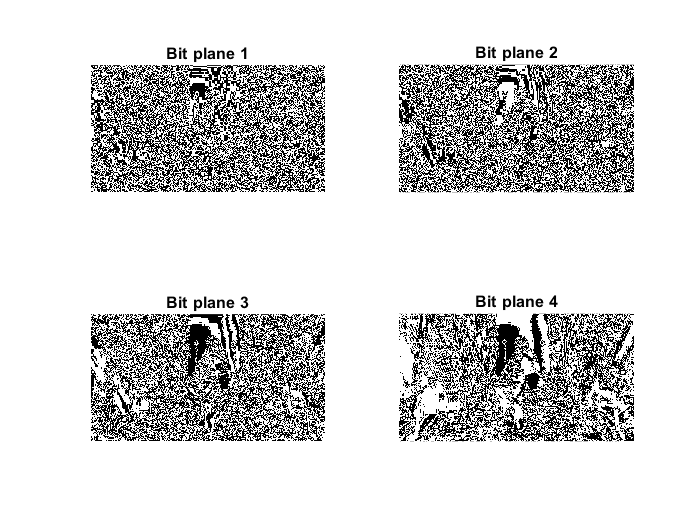



B=bitget(A,1);
figure,
subplot(2,2,1);imshow(logical(B));title('Bit plane 1');

B=bitget(A,2);
subplot(2,2,2);imshow(logical(B));title('Bit plane 2');


B=bitget(A,3);
subplot(2,2,3);imshow(logical(B));title('Bit plane 3');


B=bitget(A,4);
subplot(2,2,4);imshow(logical(B));title('Bit plane 4');

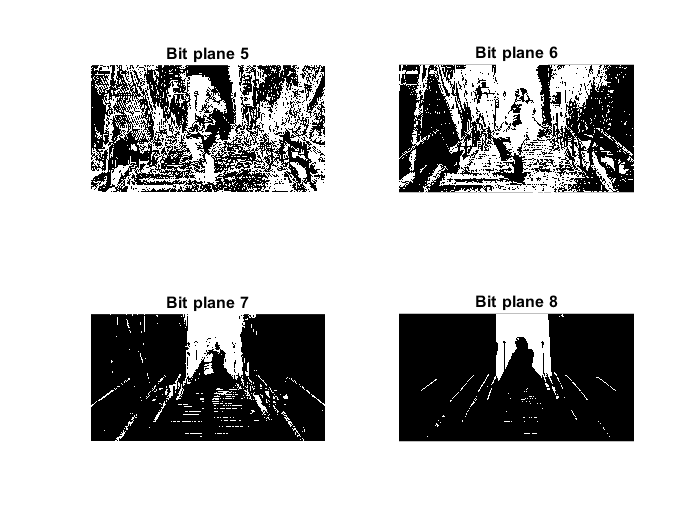



B=bitget(A,5);
figure,
subplot(2,2,1);imshow(logical(B));title('Bit plane 5');


B=bitget(A,6);
subplot(2,2,2);imshow(logical(B));title('Bit plane 6');


B=bitget(A,7);
subplot(2,2,3);imshow(logical(B));title('Bit plane 7');
imsave

B=bitget(A,8);
subplot(2,2,4);imshow(logical(B));title('Bit plane 8');

imsave

BITPLANE MERGING

A=imread('000837.jpg');
B=zeros(size(A));
B=bitset(B,8,bitget(A,8));
B=bitset(B,7,bitget(A,7));
B=bitset(B,6,bitget(A,6));
B=bitset(B,5,bitget(A,5));
B=uint8(B);
gray_reconstructed = rgb2gray(B)

gray_reconstructed = 694×1280 uint8 matrix
    0    0    0    0    0    0    0    0    0    0    0    0    0    9   11    0    0    0    9   16   16    9    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    9    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    9   11   11   16   27   32   27   32   27   32   32   27   16   11   11    0    0    0    0    2    2   11   11    0    9   11   11    9   11   11   16   27   25   16   11   11   11   11   11   11   11
   11   11   11   11   11   11   11   11    9   11   11   16   16   32   41   32   32   32   32   32   32   16   11   11    0    9    2    2   11   11   11   11    0    0    9    0    9   11   16   27   32   27   16   16   16   11   11   11    0    0
    9    9    9    9    9    9    9    9    9    9    9   11   16   27   32   32   32   32   32   32   32   16   11   11    0    0    2    2   11   11   11   11    0    0    0    0    0   11   16   27   2

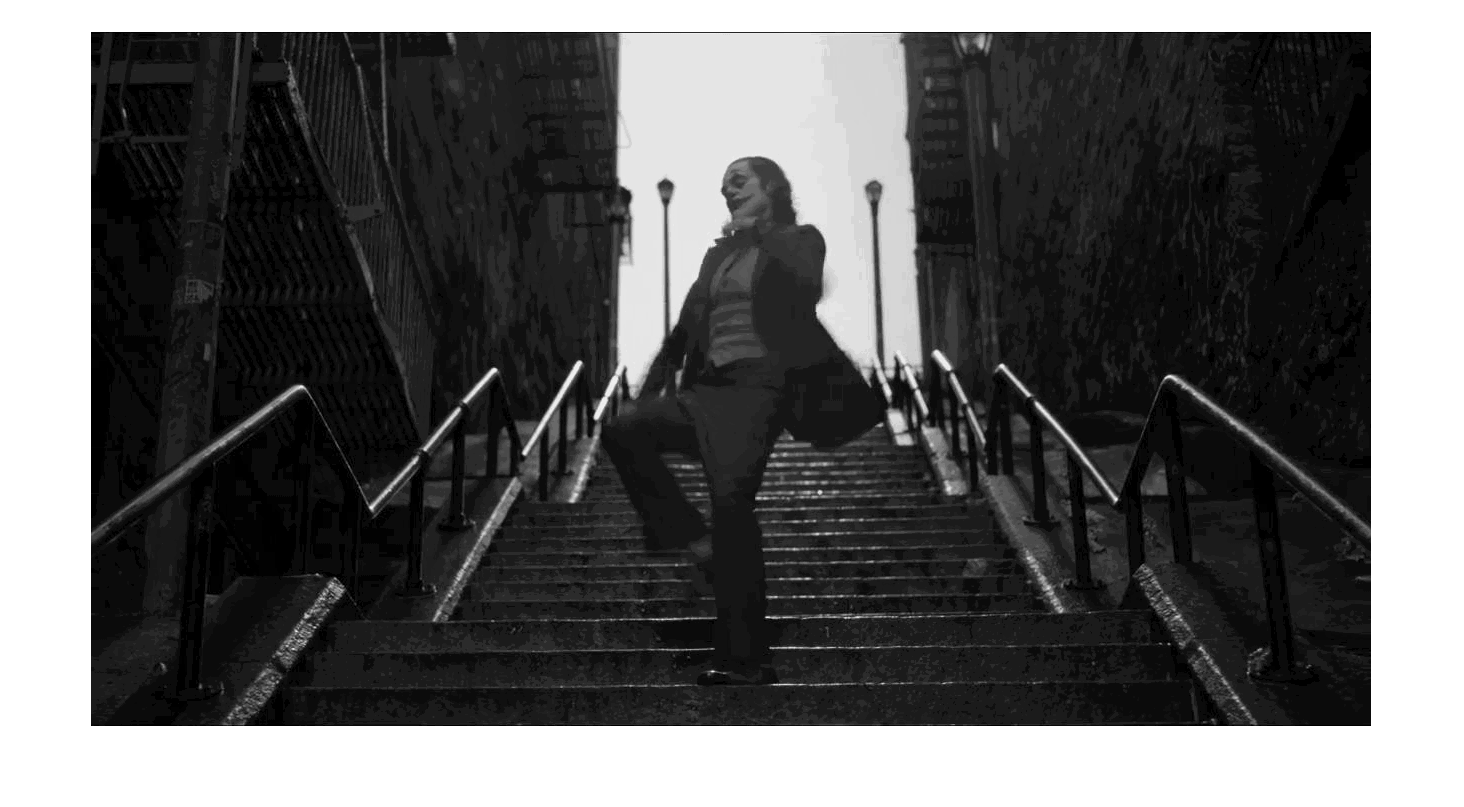

figure,
imshow(gray_reconstructed)

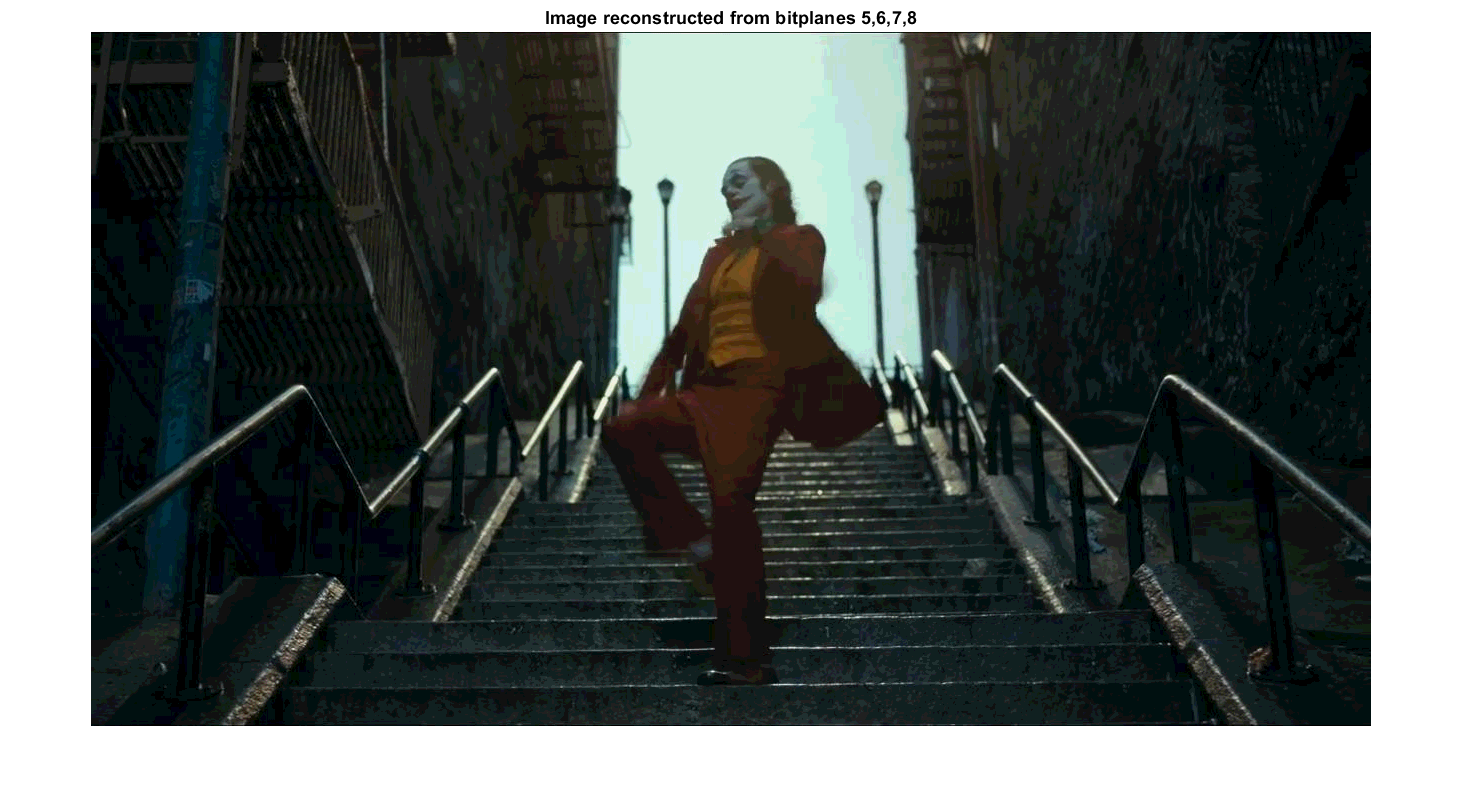

imsave
figure,imshow(B);title('Image reconstructed from bitplanes 5,6,7,8')

%imsave